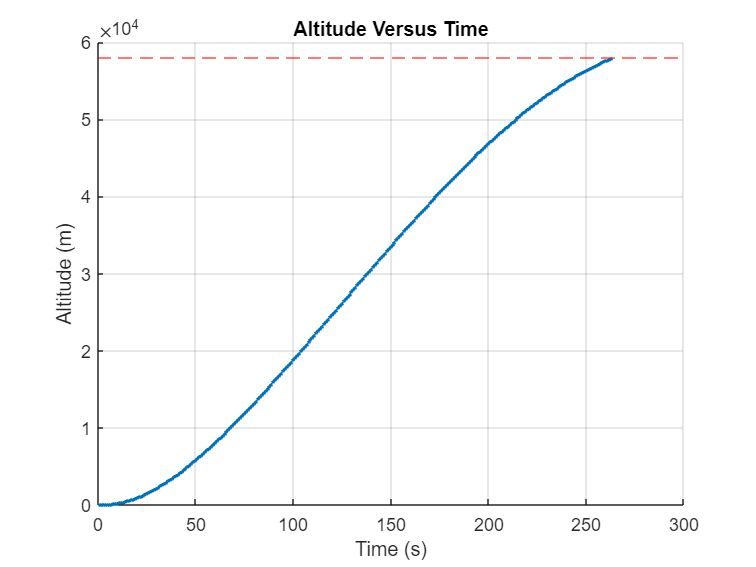

% AE414_Group10_Project_SP23

clear

g_mars_surf = 3.721; %m/s2
g_e = 9.81;          %m/s2
R_mars = 3389.5e3;   %m

tau = 170000;   %N
I_sp = 350;     %s

M_0 = 18000;    %kg
M_b = 5000;     %kg
k = 18.6;       %deg

m_dot = tau/(g_e*I_sp); %kg/s
u_eq = I_sp*g_e;        %m/s

A_f = pi*2.5^2/sin(pi/6);   %m2

u(1) = 0;
h(1) = 0;
x(1) = 0;

% Iterations

for t = 1:(M_0 - M_b)/m_dot
    
    M(t) = M_0 - m_dot*t; %kg
    
    g(t) = g_mars_surf*(R_mars/(R_mars + h(t)))^2;  %m/s2
    
    if t < 10
        theta(t) = 0;
    else
        theta(10) = k*pi/180;
        delta_theta(t) = g(t)*sin(theta(t))/u(t);
        theta(t+1) = theta(t) + delta_theta(t);
    end
         
    P(t) = 0.699*exp(-9*10^(-5)*h(t));

    if h(t)<7000
        T(t) = -31 - 9.98*10^(-4)*h(t);
    else
        T(t) = -23.4 - 2.22*10^(-3)*h(t);
    end

    rho(t) = P(t)/(0.1921*(T(t) + 273.15));
    
    Mach(t) = u(t)/sqrt(1.32*188.92*(T(t) + 273.15));
    
    if Mach(t) < 2
        C_d(t) = 0.4 + 0.3*Mach(t);
    elseif (Mach(t) < 4) && (Mach(t) > 2)
        C_d(t) = 1.2 - 0.15*Mach(t);
    else
        C_d(t) = 0.6;
    end

    D(t) = (1/2)*C_d(t)*rho(t)*u(t)^2*A_f;

    a(t) = m_dot*u_eq/M(t) - g(t)*cos(theta(t)) - D(t)/M(t);
                
    u(t+1) = u(t) + a(t);
           
    h(t+1) = h(t) + u(t)*cos(theta(t));
       
    x(t+1) = x(t) + u(t)*sin(theta(t));
    
end

t = linspace(1,length(h),length(h));

figure(1)
scatter(t,real(h),'.')
title('Altitude Versus Time')
xlabel('Time (s)')
ylabel('Altitude (m)')
yline(58000,'r--')
grid on

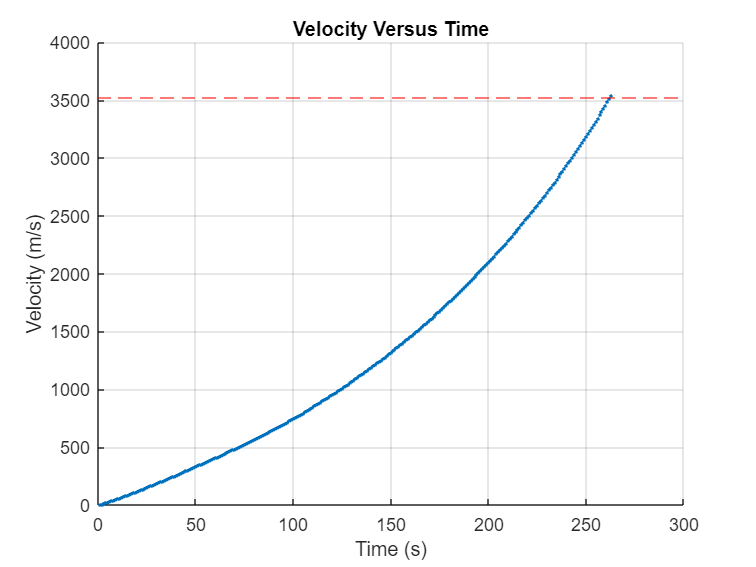


figure(2)
scatter(t,real(u),'.')
title('Velocity Versus Time')
xlabel('Time (s)')
ylabel('Velocity (m/s)')
yline(3524.636832,'r--')
grid on

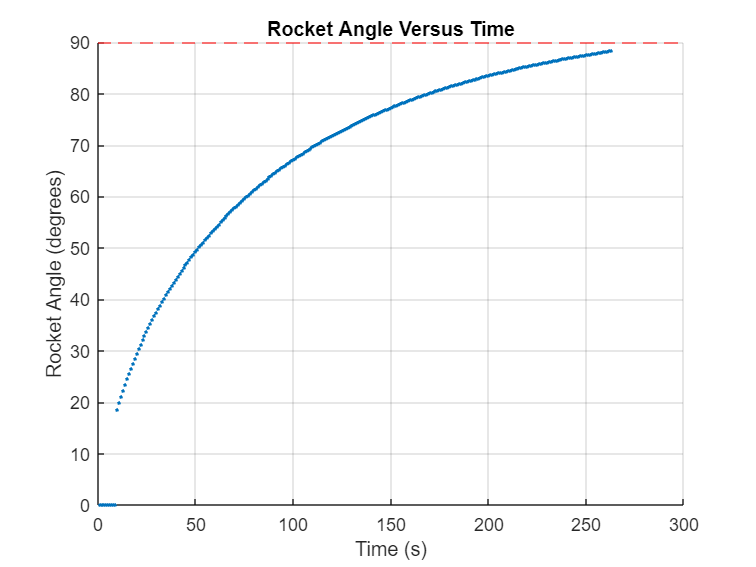


figure(3)
scatter(t,real(theta*180/pi),'.')
title('Rocket Angle Versus Time')
xlabel('Time (s)')
ylabel('Rocket Angle (degrees)')
yline(90,'r--')
grid on

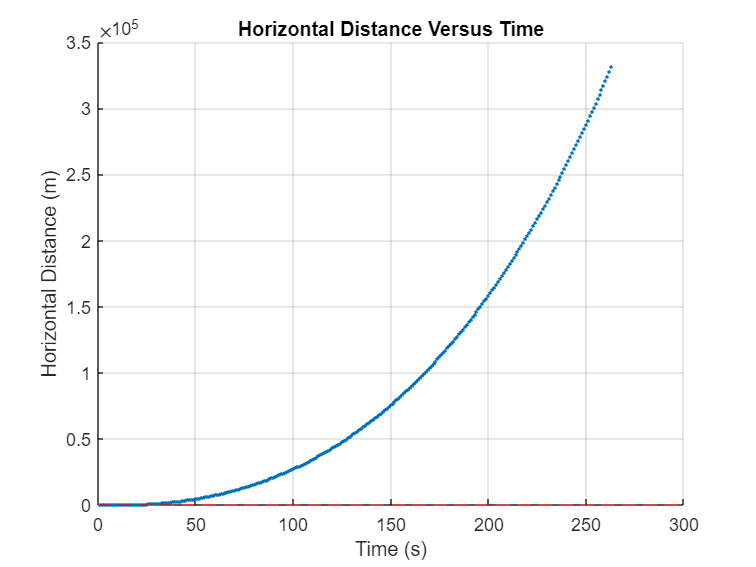


figure(4)
scatter(t,real(x),'.')
title('Horizontal Distance Versus Time')
xlabel('Time (s)')
ylabel('Horizontal Distance (m)')
yline(90,'r--')
grid on


disp(h(end))

   5.7903e+04



disp(u(end))

   3.5422e+03



disp(theta(end)*180/pi)

   88.3797



disp(x(end))

   3.3136e+05



### Task 2

mu_mars = 4.2828e4;     %km3/s2
r0 = R_mars + h(end);           %m
g0 = g_mars_surf*(R_mars/r0)^2; %m/s2
nu0 = 0.005;
IC = [1;0;1;0]; % @Tau = 0, [rho; (d/dTau)rho; (d2/dTau2)rho]


$$\begin{array}{l}
\frac{d}{d\tau }\left(\rho^2 \frac{d\theta }{d\tau }\right)=\nu \rho \\
\frac{d}{d\tau }{\left(\rho^3 \frac{d^2 \rho \;}{d\tau^2 }+\rho \;\right)}^{\frac{1}{2}} =\nu \rho \;
\end{array}$$


tspan_init = linspace(0,1000,200); %s
[Tau,S] = ode45(@eom,tspan_init,IC); 
rho = S(:,1);
drdTau= S(:,2);
B = S(:,3);
theta = S(:,4);

rdot = drdTau/sqrt(r0/g0); %m/s
r = rho*r0; %m
thetadot = B./(rho.^2); %rad/s
v = sqrt(rdot.^2 + (r.*thetadot).^2);   %m/s
t_T2 = Tau*sqrt(r0/g0);

Plot escape path using the code

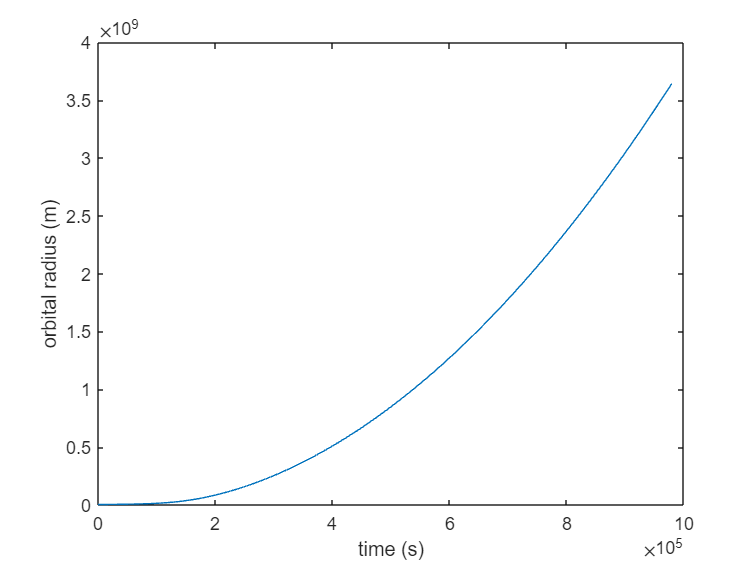

%just orbital radius for now
figure(5);
plot(t_T2,r)
xlabel("time (s)")
ylabel("orbital radius (m)")

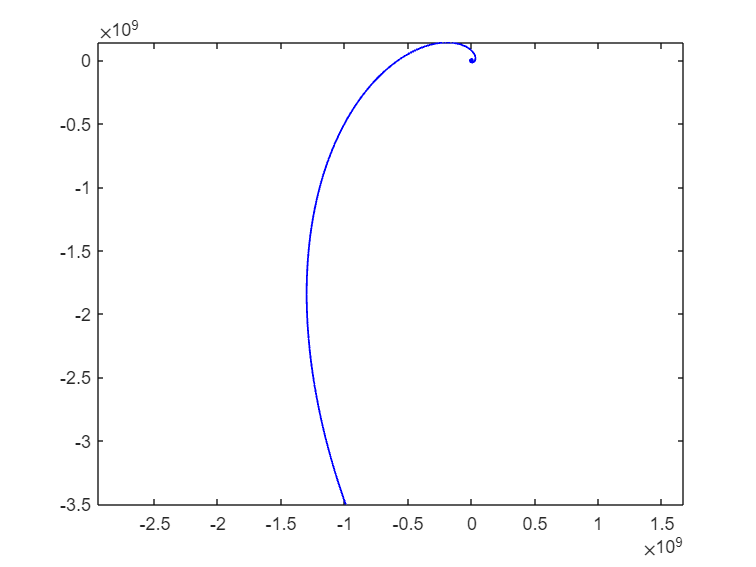

%initial orbit - circular
Ctheta = linspace(0,2*pi,200);
x = r0*cos(Ctheta);
y = r0*sin(Ctheta);

plot(x,y,"-k")
%Mars
hold on
RX = R_mars*cos(Ctheta);
RY = R_mars*sin(Ctheta);
fill(RX,RY,"r")

%To escape
vesc_t = sqrt(2*mu_mars./r);
index = find(v>vesc_t);
limit = index(1);
rx = r.*cos(theta); %r(1:limit).*cos(theta(1:limit)');
ry = r.*sin(theta); %r(1:limit).*sin(theta(1:limit)');
plot(rx,ry,"b","LineWidth",1)

axis equal
hold off

Time required to escape + escape velocity

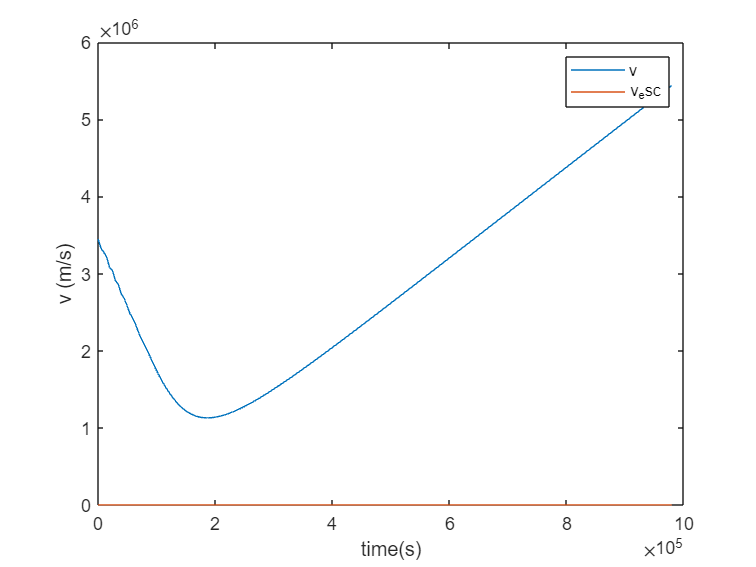

figure;
plot(t_T2,v)
hold on
plot(t_T2,vesc_t)
legend("v","v_esc")
xlabel("time(s)")
ylabel("v (m/s)")
hold off

tesc_sec = mod(t_T2(limit),60);
tesc_min = (t_T2(limit) - tesc_sec)/60;
tesc = t_T2(limit)/60;
vesc = v(limit); %m/s
fprintf("Spacecraft escapes Mars %.0f minute and %.0f seconds into the Low Thrust manuever (LTM) at %.2f m/s",tesc_min,tesc_sec,vesc)

Spacecraft escapes Mars 0 minute and 0 seconds into the Low Thrust manuever (LTM) at 3447402.75 m/s

Velocity increment ($\Delta u$) comparison

du = .005*tesc;
du_imp = (sqrt(2)-1)*sqrt(mu_mars/(r0/1000));
fprintf("\nThe velocity increment for the LTM is %f km/s while the impulsive velocity increment is %f km/s",du,du_imp)


The velocity increment for the LTM is 0.000000 km/s while the impulsive velocity increment is 1.459964 km/s

fprintf("\nDelta_u < Delta_u_impulse")


Delta_u < Delta_u_impulse

First order ODEs:


$$\begin{array}{l}
\frac{d\rho }{d\tau }=A\\
\frac{\mathrm{dA}}{d\tau }=\frac{B^2 -\rho }{\rho^3 }\\
\frac{\mathrm{dB}}{d\tau }=\nu \rho \\
\frac{d\theta }{d\tau }=\frac{B}{\rho^2 }
\end{array}$$



$$s=\left\lbrack \rho ;A;B;\theta \right\rbrack$$


function dRdT= eom(~,s) 
    nu = 0.005; %nu is constant atm
    drho = s(2);
    dA = (s(3)^2 - s(1))/(s(1)^3);
    dB = nu*s(1); 
    dtheta = s(3)/(s(1)^2);
    dRdT = [drho; dA; dB; dtheta]; 
end
